# exercise 7

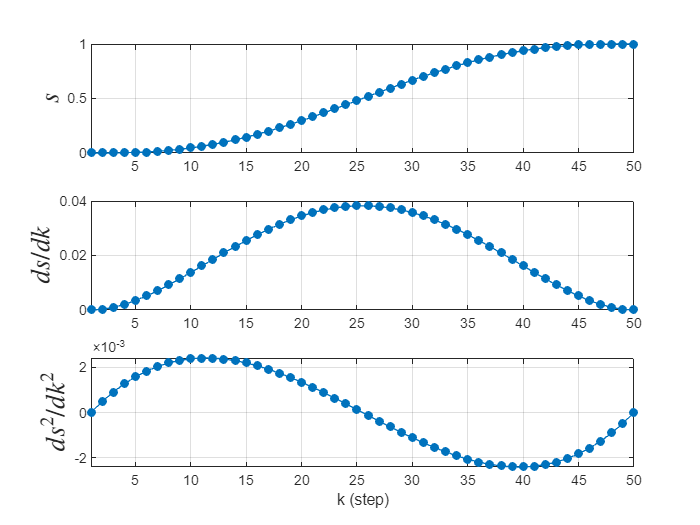


% For a tpoly trajectory from 0 to 1 in 50 steps explore the effects of different initial and
% final velocities, both positive and negative. Under what circumstances does the quintic polynomial
% overshoot and why?

% with initial veloceity =/= 0, we get overshoot in s
tpoly(0,1,50, 0,   0)

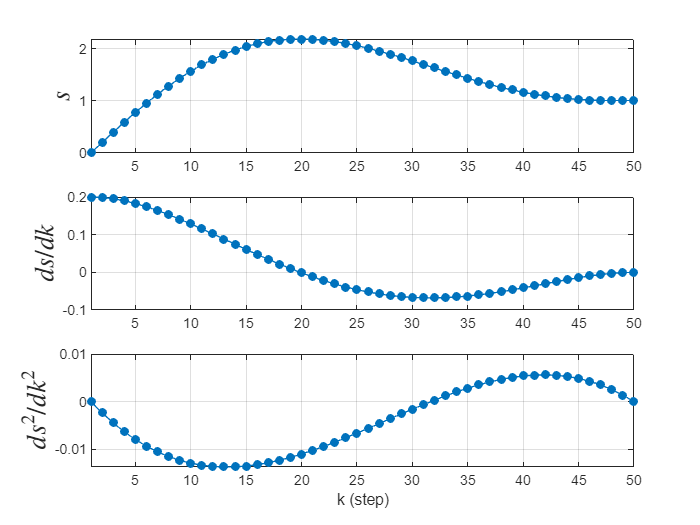

tpoly(0,1,50, 0.2, 0)

## exercise 8

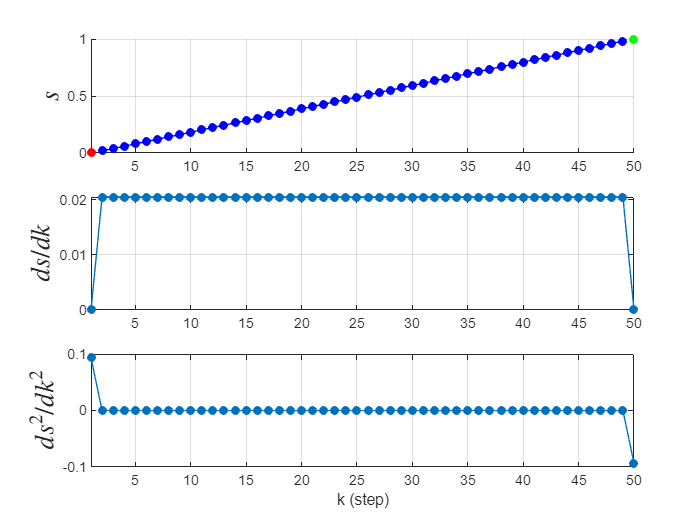

% For a lspb trajectory from 0 to 1 in 50 steps explore the effects of specifying the velocity
% for the constant velocity segment. What are the minimum and maximum bounds possible

% the minimum velocity for the linear segment is, where d is
% some small constant to avoid the entire segment from being linear, eg
% 0.0005
% (start - end)/(steps) + d
lspb(0,1,50,0.0205)

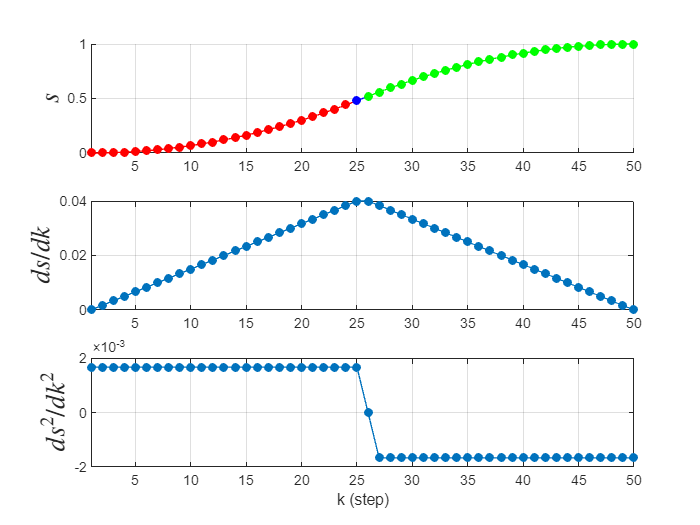

% the maximum velocity for the linear segment is
% 2*(start - end)/(steps)
% this results in have a linear segment thats a single point, 
% and anything above this results in having no linear segment (0.0405)
lspb(0,1,50,0.04)

## exercise 9

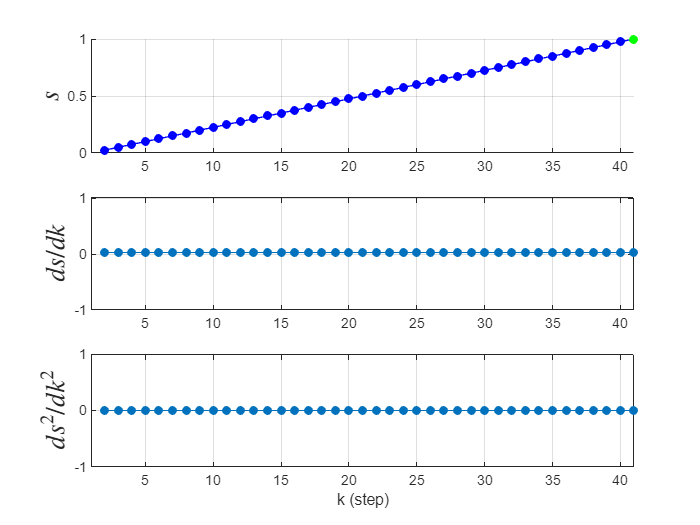

% For a trajectory from 0 to 1 and given a maximum possible velocity of 0.025 compare
% how many time steps are required for each of the tpoly and lspb trajectories?
max_vel = 0.025;
% to find the min amount of steps, we use the relationship we found in the
% last exercise, (start-end)/(steps) = vel <=> steps = (start-end)/(vel)
% however, this results in the non linear segments having 0 steps, so we
% add 1 step so we can run lspb
% steps = (start-end)/(vel) + 1
steps = 41;
lspb(0,1,steps, max_vel)

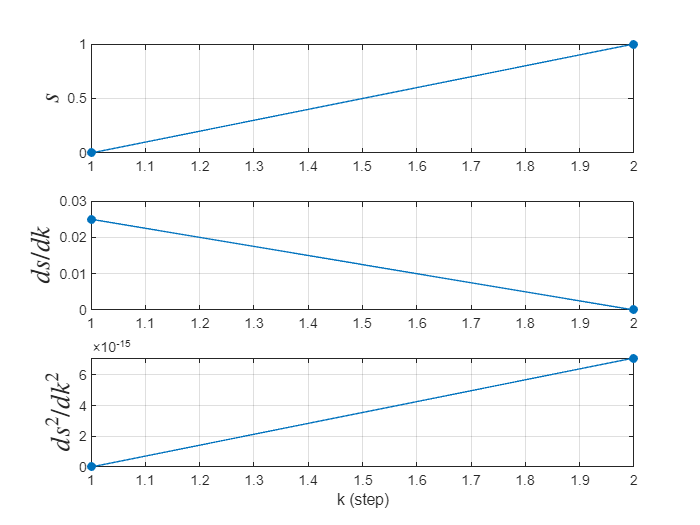

% the minimum amount of steps for the tpoly is seemingly always 2, with it
% we just get a line from start to end, and for that we obivously need
% atleast 2 points
tpoly(0,1,2,max_vel)

## exercise 13

%For the mstraj example a) Repeat with different initial and final velocity. 
% b) Investigate the effect of increasing the acceleration time. Plot total
% time as a function of acceleration time
clf
path = [
    1, 1;
    1, 2;
    2, 2;
    2, 1;
    1, 1;
]*rot2(30, 'deg')

path =     1.3660    0.3660
    1.8660    1.2321
    2.7321    0.7321
    2.2321   -0.1340
    1.3660    0.3660


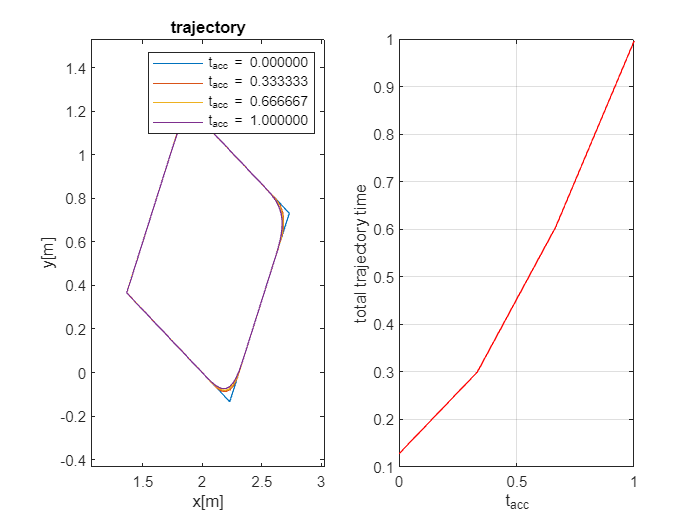

% dynamic limits
min_ = min(path(:,:));
max_ = max(path(:,:));
c = 0.3;
x_l = [min_(1)-c, max_(1)+c];
y_l = [min_(2)-c, max_(2)+c];

% increasing acceleration time, decreases the acceleration closer to the
% via points, resulting in a smoother turn on the inside of the via point
% with t_acc = 0 having inf acceleration by doing a instantaneous 90 degree
% turn in the case of the rectangle
figure(1)

QDMAX = [1,1];
% ranges of t_acc's to test
t_acc_range = 0:1/3:1;
t_acc_array = {};
total_time_array = {};
total_time = 0;
legend_entries = {};
time_step = 0.05;
for i = 1:length(t_acc_range)
    t_acc = t_acc_range(i);
    [q, t_segment] = mstraj(path, QDMAX, [], path(1,:), time_step, t_acc);

    traj_time = sum(t_segment);
    t_acc_array{end+1} = t_acc;
    total_time_array{end+1} = traj_time;

    subplot(1,2,1),plot(q(:,1), q(:,2)), xlabel('x[m]'), ylabel('y[m]'), xlim(x_l), ylim(y_l);
    legend_entries{end+1} = sprintf('t_acc = %f', t_acc);  
    hold on
end 
title('trajectory')
legend(legend_entries)
hold off
subplot(1,2,2)
plot(cell2mat(t_acc_array), cell2mat(total_time_array)./1000, '-r');
xlabel('t_{acc}');
ylabel('total trajectory time');
grid on;